# ISET3d: Materials

*This tutorial mostly works.  But it is not clear enough and should be edit.*

PBRT scene materials are stored in this slot **thisR.materials.   **A single material can be used to describe multiple objects in the scene. 

The material slot is a struct that contains a number of useful entries.  The Simple Scene contains eight different materials.

The materials are stored as a Matlab 'map', which makes them easier to search through for large, complicated scenes.  Some of our scenes use a thousand different materials.

We read and write material properties using the usual set/get method

Setting material properties is essential for making realistic scenes.  We are constantly documenting and adding guides to specify materials with understandable names and properties. There was a substantial change in material properties in PBRT V4.0 so we are not likely to run out of tasks any time soon.

A material has many properties that define the object's color, surface roughness, specularity, and opacity. The color properties are separated in diffusion reflectance (kd), specular reflectance (ks), and mirror reflectance (kr).   We can specify the color in various ways, including RGB and spectral reflectance.

This tutorial illustrates how to set/get material properties and how to create new materials.

**See also**

  t_materials.m, piMaterialCreate, t_assets, t_piIntro*

## The base scene

This is the low resolution simple scene. We will introduce a set of material changes

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 7 materials and 1 textures.
Attribute processing: Ignoring Rotate: Rotate 0 0 1 0
Ignoring Rotate: Rotate -90 1 0 0
Ignoring Scale: Scale 1 1 1
Ignoring Rotate: Rotate 90 -1 0 0
Ignoring Scale: Scale 1 -1 1
Identified 9 assets; parsed up to line 103


Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (0.39 sec)
Command: docker --context remote-orange exec -it  pbrt-gpu-wandell4404 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.p

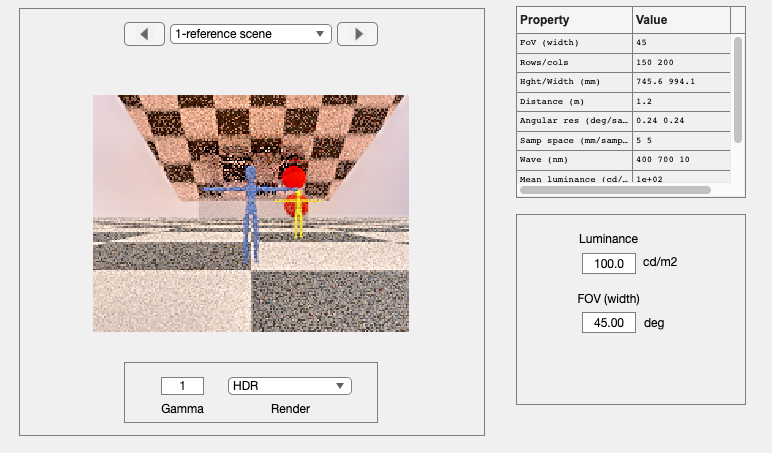

thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5); 

piWRS(thisR,'name','reference scene','render flag','hdr');

## List the scene materials

To list the materials in the scene, use this command

thisR.show('materials');


Scene materials: SimpleScene
-------------------------------
            name            type     
         ___________    _____________

    1    <undefined>    coateddiffuse
    2    BODY           diffuse      
    3    GLASS          dielectric   
    4    Material       coateddiffuse
    5    mirror         conductor    
    6    uber           coateddiffuse
    7    uber_blue      coateddiffuse

-------------------------------


## The material of an asset

Each asset (object node in the tree) has a material name.  We find the material for an object this way.

% The material of the blue stick figure
assetFig3m = piAssetSearch(thisR,'object name','figure_3m'); 
thisR.get('asset',assetFig3m,'material name')

ans = 'uber_blue'

The material of the ceiling will become a mirror.  For now it is the black surface at the ceiling.

assetMirror = piAssetSearch(thisR,'object name','mirror'); 
thisR.get('asset',assetMirror,'material name')

ans = 'mirror'

## Material properties

We get a material from its name.  We can also get just a specific property.

Find a material and print its properties

matName = 'uber_blue';
thisMat = thisR.get('material', matName)

thisMat = struct with fields:
              name: 'uber_blue'
      fluorescence: [1×1 struct]
     concentration: [1×1 struct]
              type: 'coateddiffuse'
       reflectance: [1×1 struct]
               eta: [1×1 struct]
         roughness: [1×1 struct]
        uroughness: [1×1 struct]
        vroughness: [1×1 struct]
    remaproughness: [1×1 struct]
          maxdepth: [1×1 struct]
          nsamples: [1×1 struct]
                 g: [1×1 struct]
            albedo: [1×1 struct]
         normalmap: [1×1 struct]
      displacement: [1×1 struct]
         thickness: [1×1 struct]


Check roughness

roughness = thisR.get('material', matName, 'roughness')

roughness = struct with fields:
     type: 'float'
    value: 0.5000


Check diffuse property

reflectance = thisR.get('material', matName, 'reflectance')

reflectance = struct with fields:
     type: 'rgb'
    value: [0.0477 0.1075 0.3424]


Check specular reflection property

%% need v4

Check mirror reflection property

%% need v4 kt = thisR.get('material', matName, 'kr')

Check property type (spectral, rgb)

kdType = thisR.get('material', matName, 'type')

kdType = 'coateddiffuse'

## Set material color: RGB format

The blue guy wants to be green today.

Change diffuse reflectance to be green

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (0.38 sec)
Command: docker --context remote-orange exec -it  pbrt-gpu-wandell4404 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.p

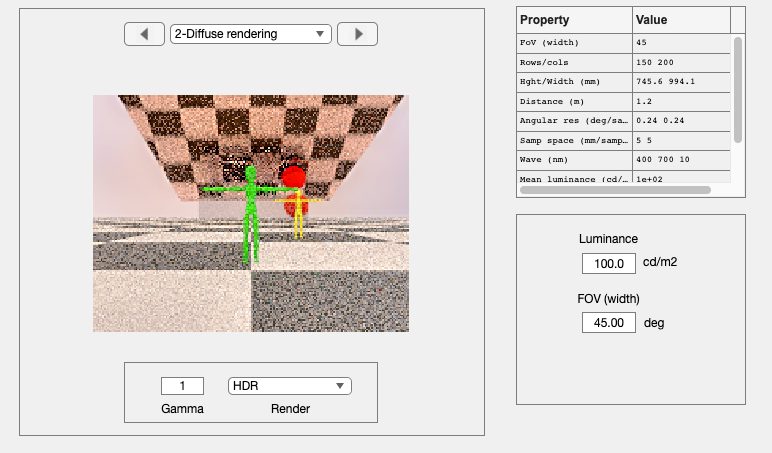

thisR.set('material', matName, 'reflectance', [0 0.5 0]);
piWRS(thisR,'name','Diffuse rendering','render type','radiance');

## Set material type: glass

The blue guy is feeling like glass, now.  So make a glass material.

glassMaterial = 'blueGuyGlass';
newMat = piMaterialCreate(glassMaterial, 'type', 'dielectric');
thisR.set('material', 'add', newMat);

Print the blue figure material and then change it to glass.

assetName = thisR.get('asset',assetFig3m,'name')

assetName = '000021ID_figure_3m_O'

curName = thisR.get('asset', assetFig3m, 'material name');
fprintf('The material for %s is %s\n',assetName,curName);

The material for 000021ID_figure_3m_O is uber_blue


Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (0.41 sec)
Command: docker --context remote-orange exec -it  pbrt-gpu-wandell4404 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.p

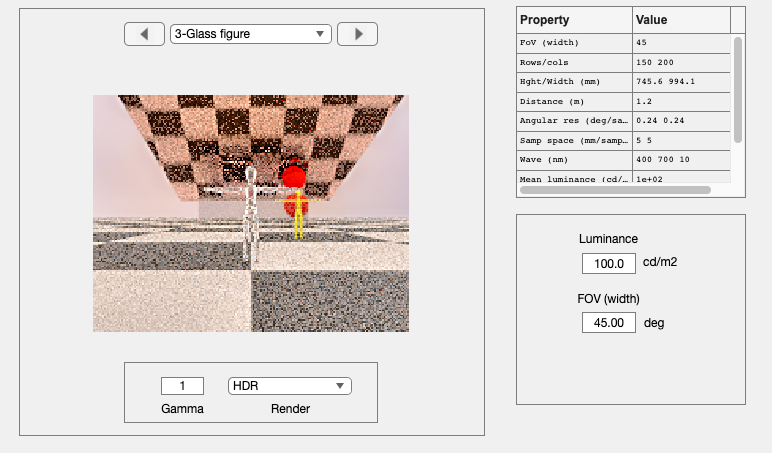

thisR.set('asset', assetFig3m, 'material name', glass);
piWRS(thisR,'name','Glass figure','render type', 'radiance'); 

## Set material type: mirror

Create a mirror material

materialName = 'newMirror';
newMat = piMaterialCreate(materialName, 'type', 'conductor');
thisR.set('material', 'add', newMat);

This is the current black ceiling, and we change it to a mirror

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (0.41 sec)
Command: docker --context remote-orange exec -it  pbrt-gpu-wandell4404 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.p

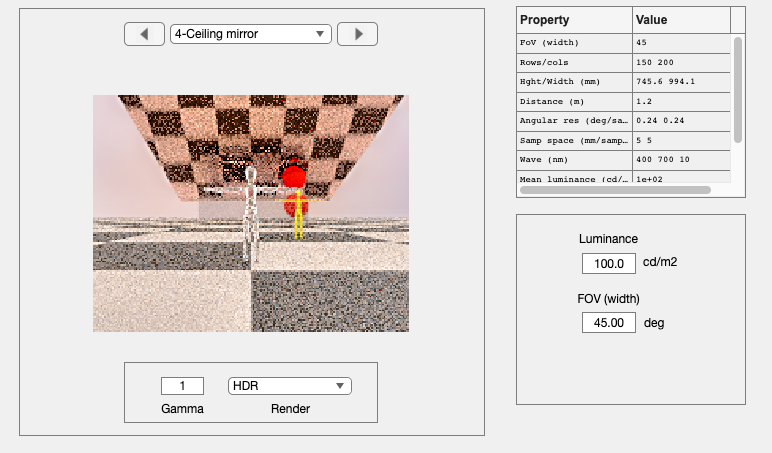

curName = thisR.get('asset', assetMirror, 'material name');
thisR.set('asset', assetMirror, 'material name', materialName);
piWRS(thisR,'name','Ceiling mirror','render type','radiance');

## Set material spectral reflectance

We can also specify the color using a spectral reflectance function

This is still the ceiling. Set the spectral reflectance of the matte material to the reflectance of the 10th chip in the MCC.  It is very red.

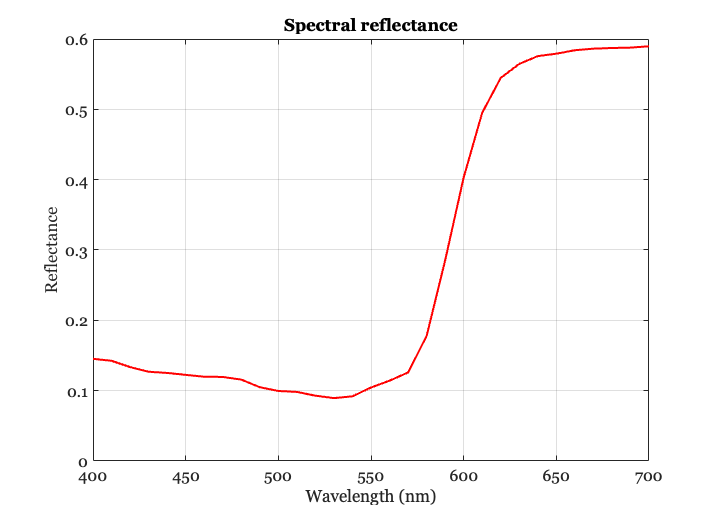

wave = 400:10:700;
mccRefs = ieReadSpectra('macbethChart', wave);
thisRef = mccRefs(:, 10);
ieNewGraphWin;
plotReflectance(wave,thisRef);

redName = 'newMatte';
redMaterial = piMaterialCreate(redName, 'type', 'diffuse');
thisR.set('material', 'add', redMaterial);

Convert the reflectance to the PBRT spd format.  It is (wave, value) ...

spdRef = piMaterialCreateSPD(wave, thisRef);

Store the spd reflectance as the diffuse reflectance of the newMatte material

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (0.39 sec)
Command: docker --context remote-orange exec -it  pbrt-gpu-wandell4404 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.p

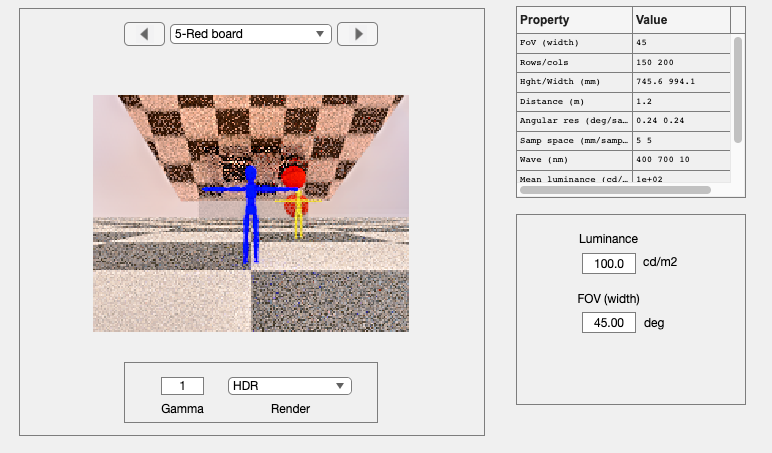

thisR.set('material', redName, 'reflectance', [0 0 1]);
thisR.set('asset', assetFig3m, 'material name', redName);
piWRS(thisR,'name','Red board','render type','radiance');

% sceneSet(scene, 'render flag', 'hdr');

## Delete unused material

The blue guy never wants to be blue any more.

thisR.show('materials');


Scene materials: SimpleScene
-------------------------------
              name            type     
          ____________    _____________

    1     <undefined>     coateddiffuse
    2     BODY            diffuse      
    3     GLASS           dielectric   
    4     Material        coateddiffuse
    5     blueGuyGlass    dielectric   
    6     mirror          conductor    
    7     newMatte        diffuse      
    8     newMirror       conductor    
    9     uber            coateddiffuse
    10    uber_blue       coateddiffuse

-------------------------------


Delete uber material

deleteName = 'uber';
thisR.set('material', 'delete', deleteName);
thisR.show('materials');


Scene materials: SimpleScene
-------------------------------
             name            type     
         ____________    _____________

    1    <undefined>     coateddiffuse
    2    BODY            diffuse      
    3    GLASS           dielectric   
    4    Material        coateddiffuse
    5    blueGuyGlass    dielectric   
    6    mirror          conductor    
    7    newMatte        diffuse      
    8    newMirror       conductor    
    9    uber_blue       coateddiffuse

-------------------------------
